# Comparison between Regression Network, MUSIC, and ESPRIT

Plot average perturbation multiplier on the x-axis versus RMSE for each method. Average over 10 samples for each of the 50 perturbation multipliers. 

### Load Dataset into Workspace

Only doing Validation and Testing: No Training Dataset Needed

% Initialization: 
close all;clc; 
% clear all; % commented to prevent clearing out the workspace
cd("C:\Users\mathe\Documents\MATLAB\Thesis Codes and Figures\ThesisDatasetsAndNeuralNetwork");
% setup file for Matlab figures
set(0,'DefaultAxesFontSize',18)
set(0,'DefaultLineLineWidth',2)
set(0,'DefaultTextFontSize',18)
legend_font_size = 12;

% Loading Datasets: 
validate_filename = 'validation_data_array_perturbations.h5';
% test_filename = 'testing_data_array_perturbations.h5';
% file_names = {train_filename,validate_filename,test_filename};
cd("HDF5_File_Location");

% load in data to struct using HDF2Struct:
% Syntax:  data = HDF2Struct(file_name, verbose)
validate_data = HDF2Struct(validate_filename);

cd ..
overarching_foldername = 'Training_And_Validation_DataReal_Imag_Phase';
validate_foldername = 'ValidationData5x5Image';

cd(overarching_foldername);
% Try with un-normalized Data for Validation and Training 
validate_labels_deg = validate_data.dataset_theta;

% Create Validate Data datastore 
validate_datastore_images = imageDatastore(validate_foldername); 
validate_labels_datastore = arrayDatastore(validate_labels_deg,IterationDimension=3);
validate_datastore = combine(validate_datastore_images,validate_labels_datastore);

cd .. % back out to main directory where this script is stored

### Configure Chosen Random Samples for testing outputs from each network on

% number of known avg perturb mults and samples per each
% determine number of unique categories
categorical_validate = categorical(validate_data.dataset_arr_perturb_mult);
categories_validate = categories(categorical_validate);
categories_validate_matrix = str2double(categories_validate);
num_perturb_mults = size(categories_validate,1);

validate_num_samples = size(validate_data.dataset_arr_perturb_elem,3); 
validate_samps_per_mult = validate_num_samples/num_perturb_mults; % 250
% number samples to average over for each of the 50 perturb mults - 250
% sample total per perturb mult
num_average_50_mults = 50;

% use same sample numbers just summed with "validate_num_samples" for each
% perturb multiplier: add "validate_samps_per_mult" for each
% iteration/point on plot for comparing values
test_img_numbers_initial = randi([1 validate_samps_per_mult],1,num_average_50_mults); 

### Load Neural Network into Dataspace

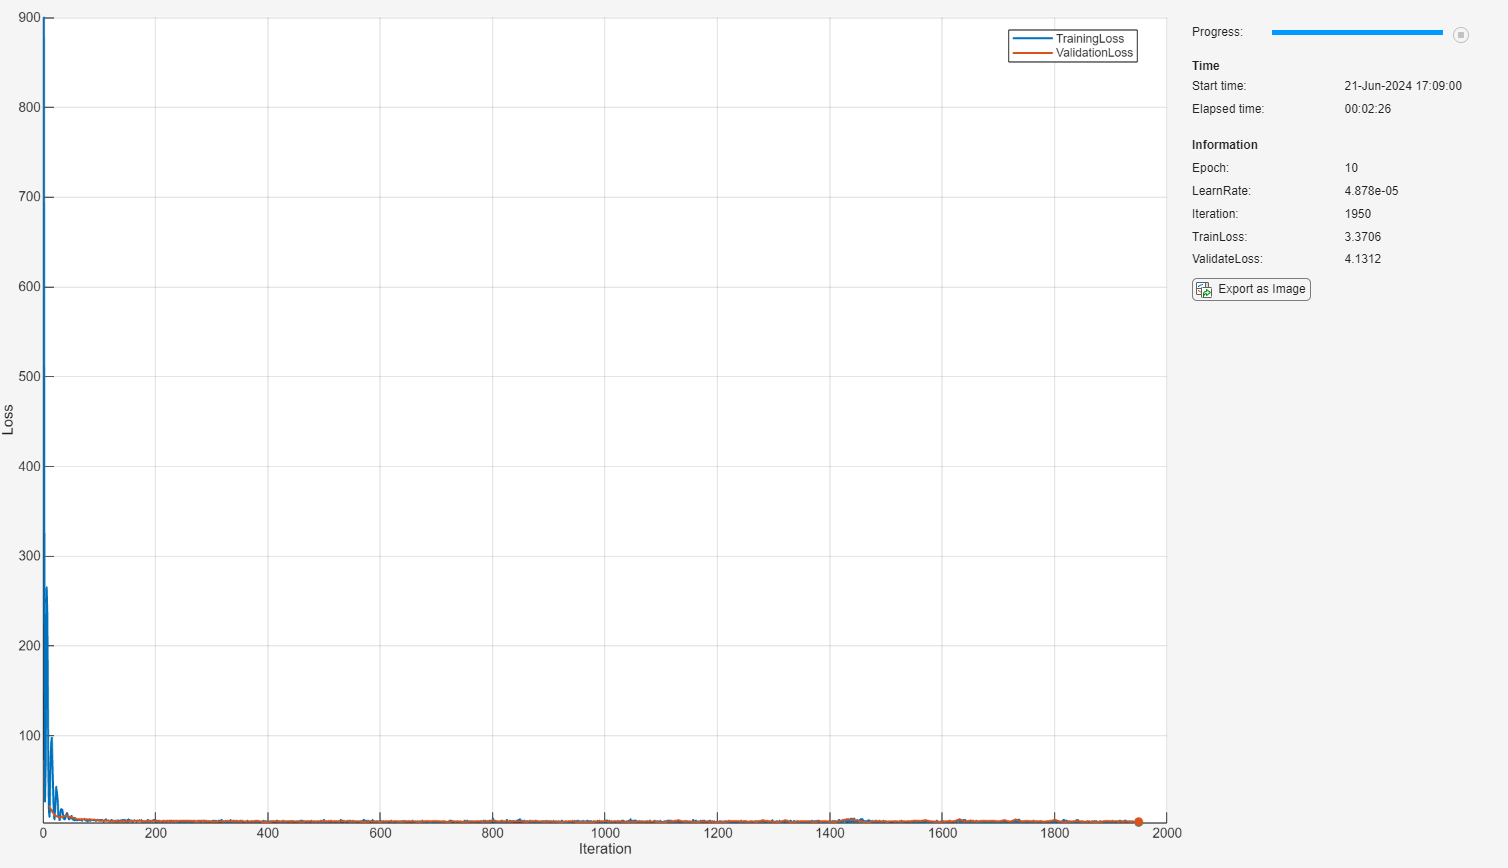

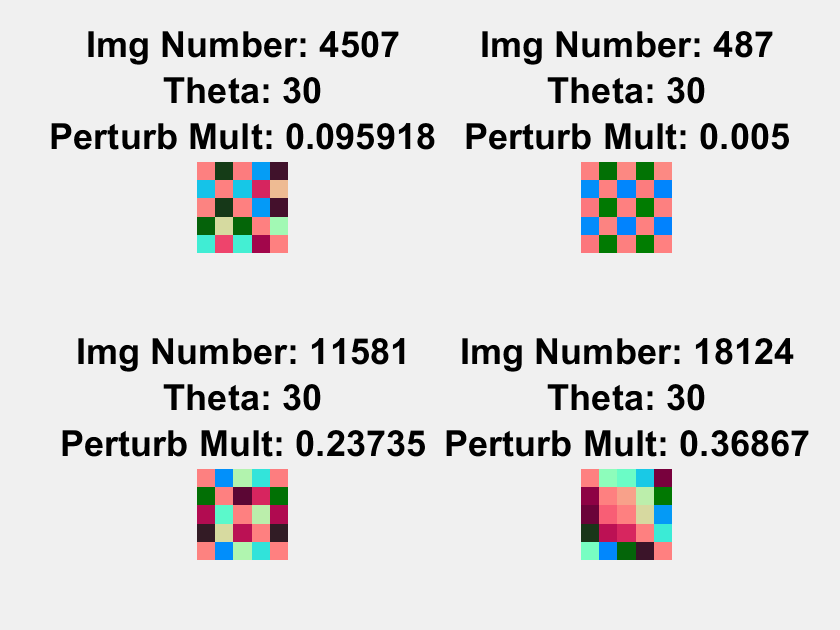

% Load network into Workspace
% cd("C:\Users\mathe\Documents\MATLAB\Thesis Codes and Figures\ThesisDatasetsAndNeuralNetwork")

% Uncomment for entire workspace:
load DCNNThesisWorkspace.mat

% Uncomment for just Neural Network: 
% load DeepCNNArrayPerturb1.mat

### Determine Outputs from each and average the RMSE over 10 samples

iterate through 50 avg perturbation multipliers 

test_img_numbers = for the current perturbation multipler. For each one the values are incremented by 250 or "`validate_samps_per_mult`"

% Iterate 50 times to average the result for each perturbation multiplier.
% initialization
avg_mse_per_perturbation = zeros(num_perturb_mults,1);
avg_abs_per_perturbation = zeros(num_perturb_mults,1); 
all_dcnn_outputs = zeros(num_perturb_mults*num_average_50_mults,1);
test_img_numbers = test_img_numbers_initial;

for i=1:num_perturb_mults
    avg_sample_sum_mse = 0;
    avg_sample_sum_abs = 0;
    for j = 1:num_average_50_mults
    current_img_number = test_img_numbers_initial(j);
    current_image = readimage(validate_datastore.UnderlyingDatastores{1},current_img_number);
    % Convert image to double for use in dlarray for forward propaget thru network
    current_sample = dlarray(double(current_image)); 
    % Obtain network DOA Estimate & Store - forward() also works
    dcnn_current_output = predict(network_topology,current_sample);
    % store all DOA estimates from DCNN 
    % multiplied by "num_average_50_mults" not j (max(j))
    all_dcnn_outputs((i-1)*num_average_50_mults+j) = dcnn_current_output;
    current_label = validate_data.dataset_theta(current_img_number);
    dcnn_current_mse = (dcnn_current_output-current_label)^2;
    dcnn_current_abs = abs(dcnn_current_output-current_label);
    avg_sample_sum_mse = avg_sample_sum_mse + dcnn_current_mse;
    avg_sample_sum_abs = avg_sample_sum_abs + dcnn_current_abs;
    end
    % Increment randomly determined test image numbers by 250 
    test_img_numbers = test_img_numbers + validate_samps_per_mult;
    % Insert average of 10 samples to current avg perturb mult estimate
    avg_mse_per_perturbation(i) = avg_sample_sum_mse/num_average_50_mults; 
    avg_abs_per_perturbation(i) = avg_sample_sum_abs/num_average_50_mults; 
end

## Testing Compared to MUSIC and ESPRIT

Example Use Case

% function [music_doa_estimation,angle_out] = MUSIC_DOA_Estimate(signal_in,varargin)
% function angle_out = ESPRIT_DOA_Estimate(signal_in,varargin)

% take MUSIC spectrum for each sample_per_multiplier
% [music_doa_estimation,angle_out_current] = MUSIC_DOA_Estimate(signal_in,...
%    rand_seed,search_space, theta_in,element_position,SNR_in);
		
% take ESPRIT spectrum - angle_out_current only possible output of ESPRIT function 
%angle_out_current_ESPRIT = ESPRIT_DOA_Estimate(signal_in,rand_seed,...
%    theta_in,element_position,SNR_in);

Use For determining errors from sample samples from the testing samples: 

% Pre-allocating comparison standards 
% Estimates are 10 (num_average_50_mults) total 1 for each Test Sample in 
% each Perturbation Multiplier -> Error are 50 total (num_perturb_mults)
% Initialization
MUSICTestDOAErrors_MSE = zeros(num_perturb_mults,1); 
MUSICTestDOAErrors_ABS = zeros(num_perturb_mults,1); 
allMUSICEstimates = zeros(num_perturb_mults*num_average_50_mults,1);
ESPRITTestDOAErrors_MSE =  zeros(num_perturb_mults,1);
ESPRITTestDOAErrors_ABS =  zeros(num_perturb_mults,1);
allESPRITEstimates = zeros(num_perturb_mults*num_average_50_mults,1);

test_img_numbers = test_img_numbers_initial;

% Creating original non-perturbed values -> use file/function: "initialize_params.m"
% Then just grab element perturbations 
theta_signals = 30; N = 5; d_exp = 0.5; SNR_in = 20; sig_amp = ones(1,length(theta_signals)); num_snapshots = 1000;
search_space = linspace(-90,90,181); % 1 degree resolution over search space
% rand_seed=11; % defined above
[signal_in,noise,x_expected] = initialize_params(theta_signals,N,d_exp,SNR_in,sig_amp,rand_seed,num_snapshots);

for i=1:num_perturb_mults % 50 iters
    % reset error values after averaging
    total_mse_MUSIC_error = 0;
    total_abs_MUSIC_error = 0;
    total_mse_ESPRIT_error = 0;
    total_abs_ESPRIT_error = 0;
    for j = 1:num_average_50_mults % 10 iters
        curr_samp_num = test_img_numbers(j);
        current_dataset_theta_label = validate_data.dataset_theta(:,:,curr_samp_num);
        % Perturbations aren't stored in the datastore, but are in HDF5 file
        current_dataset_perturbed_pos = validate_data.dataset_arr_perturb_elem(:,:,curr_samp_num);
        % Compute MUSIC DOA Estimate 
        theta_in = current_dataset_theta_label;
        element_position = x_expected + current_dataset_perturbed_pos;
        % Don't need entire MUSIC subspectra 
        [~,MUSICTestDOAEstimates] = MUSIC_DOA_Estimate(signal_in,...
            rand_seed,search_space, theta_in,element_position,SNR_in);
        % set MUSIC estimate to 0° if NAN or no result appears: 
        if isempty(MUSICTestDOAEstimates)
            MUSICTestDOAEstimates = 0;
        end
        % else peak is found for MUSIC: 
        % Order is: (i-1)*(max(j)) + j 
        allMUSICEstimates((i-1)*num_average_50_mults+j) = MUSICTestDOAEstimates;
        current_MUSIC_MSE = (MUSICTestDOAEstimates-current_dataset_theta_label)^2;
        current_MUSIC_ABS = abs(MUSICTestDOAEstimates-current_dataset_theta_label);
        total_mse_MUSIC_error = total_mse_MUSIC_error + current_MUSIC_MSE;
        total_abs_MUSIC_error = total_abs_MUSIC_error + current_MUSIC_ABS;
        % Compute ESPRIT Errors for each estimate of 10 by summing MSE and
        % divide at end 
        ESPRITTestDOAEstimates = ESPRIT_DOA_Estimate(signal_in,rand_seed,...
        theta_in,element_position,SNR_in);
        allESPRITEstimates((i-1)*num_average_50_mults+j) = ESPRITTestDOAEstimates;
        current_ESPRIT_MSE = (ESPRITTestDOAEstimates-current_dataset_theta_label)^2;
        current_ESPRIT_ABS = abs(ESPRITTestDOAEstimates-current_dataset_theta_label);
        total_mse_ESPRIT_error = total_mse_ESPRIT_error + current_ESPRIT_MSE;
        total_abs_ESPRIT_error = total_abs_ESPRIT_error + current_ESPRIT_ABS;
    end
    test_img_numbers = test_img_numbers + validate_samps_per_mult;
    MUSICTestDOAErrors_ABS(i) = total_abs_MUSIC_error/num_average_50_mults;
    MUSICTestDOAErrors_MSE(i) = total_mse_MUSIC_error/num_average_50_mults;
    ESPRITTestDOAErrors_ABS(i) = total_abs_ESPRIT_error/num_average_50_mults;
    ESPRITTestDOAErrors_MSE(i) = total_mse_ESPRIT_error/num_average_50_mults;

end
% All MUSIC and ESPRIT Estimates stored in:
% allMUSICEstimates & allESPRITEstimates

### Plotting Outputs

Plotted Logarithm of the MSE because MSE was super high because many of the MUSIC samples were not found to have a max value in the peak finder

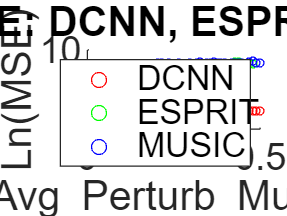

% categories_validate_matrix: x-value avg perturbation multipliers used 
dcnn_vs_music_vs_esprit = figure(100);
scatter_size = 10; 
% Take the logarithm of MSE for MUSIC,ESPRIT,& DCNN 
logESPRITTestDOAErrors = log(ESPRITTestDOAErrors_MSE);
logMUSICTestDOAErrors = log(MUSICTestDOAErrors_MSE);
% DCNN MSE:
logavg_mse_per_perturbation = log(avg_mse_per_perturbation);

scatter(categories_validate_matrix,logavg_mse_per_perturbation,scatter_size,'r'); hold on;
scatter(categories_validate_matrix,logESPRITTestDOAErrors,scatter_size,'g'); hold on;
scatter(categories_validate_matrix,logMUSICTestDOAErrors,scatter_size,'b'); hold on;

%scatter(categories_validate_matrix,avg_mse_per_perturbation,scatter_size,'r'); hold on;
% have to manually determine MSE by taking error term, squaring the value, summing, and mult by 1/N 
%scatter(categories_validate_matrix,ESPRITTestDOAErrors,scatter_size,'g'); hold on;
% scatter(categories_validate_matrix,MUSICTestDOAErrors,scatter_size,'b'); hold on;

title("Log RMSE: DCNN, ESPRIT, & MUSIC"); 
xlabel("Avg Perturb Mult \lambda"); 
ylabel("Ln(MSE)");
legend("DCNN","ESPRIT","MUSIC")


% saveas(dcnn_vs_music_vs_esprit,"DCNN Comparison With MUSIC and ESPRIT 10 Average Samples Each Perturb Mult.jpg");
saveas(dcnn_vs_music_vs_esprit,"MSE Log - DCNN Comparison With MUSIC and ESPRIT 10 Average Samples Each Perturb Mult.jpg");

### Try Plotting Absolute Error

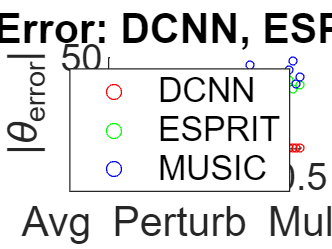

absolute_error_comparison = figure(200);
% categories_validate_matrix: x-value avg perturbation multipliers used 
scatter_size = 10; 

scatter(categories_validate_matrix,avg_abs_per_perturbation,scatter_size,'r'); hold on;
scatter(categories_validate_matrix,ESPRITTestDOAErrors_ABS,scatter_size,'g'); hold on;
scatter(categories_validate_matrix,MUSICTestDOAErrors_ABS,scatter_size,'b'); hold on;

%scatter(categories_validate_matrix,avg_mse_per_perturbation,scatter_size,'r'); hold on;
% have to manually determine MSE by taking error term, squaring the value, summing, and mult by 1/N 
%scatter(categories_validate_matrix,ESPRITTestDOAErrors,scatter_size,'g'); hold on;
% scatter(categories_validate_matrix,MUSICTestDOAErrors,scatter_size,'b'); hold on;

title("Absolute Error: DCNN, ESPRIT, & MUSIC"); 
xlabel("Avg Perturb Mult \lambda"); 
ylabel("|\theta_{error}|");
legend("DCNN","ESPRIT","MUSIC")

saveas(absolute_error_comparison,"Absolute Error - DCNN Comparison With MUSIC and ESPRIT 10 Average Samples Each Perturb Mult.jpg");